# Run the optimisation.

StartDate = datetime('2021-01-01')

StartDate = datetime
   01-Jan-2021


MaxVaccinesPerDay = (7.4e6 + 1.8e6 + 14.9e6) / 365

MaxVaccinesPerDay = 6.6027e+04

Lethality = [0.00022274,0.00022274,0.00022274,0.00022274,0.00022274,0.00221398,0.01351613,0.134212];
P = lib.classes.OptProblem(...
    'CostFunc', 'total_deaths', ...
    'CostFuncParams', Lethality, ...
    'VaccineEfficacy', 0.95, ...
    'StartDate', StartDate, ...
    'MaxVaccinesPerDay', MaxVaccinesPerDay, ...
    ... 'ReprNum', 1.5, ...
    'Steps', 365 ...
);

## Normal situation.

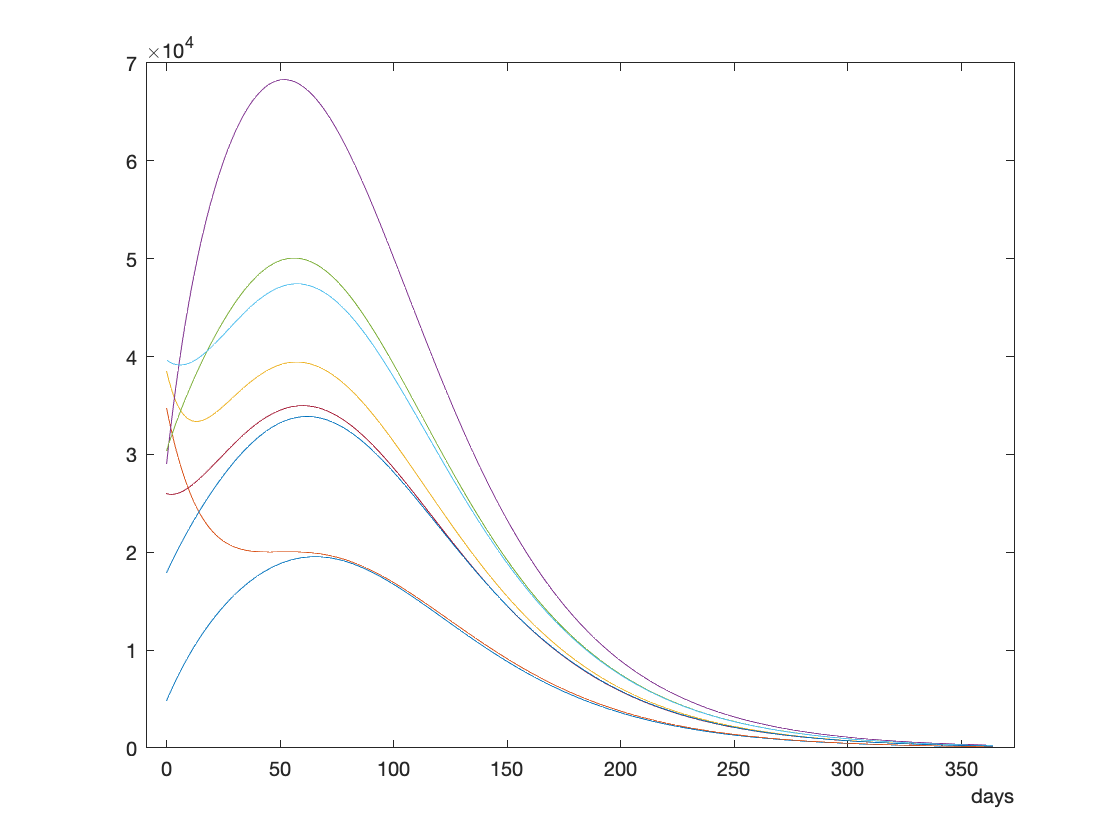

NMR = P.getResult();
figure;
plot(NMR.T, NMR.I');

## Genetic Algoritm.

[ga_VS, ga_score] = P.runGeneticAlgorithm( ...
    'MaxGenerations', 5100, ...
    'MaxStallGenerations', inf, ... 
    'InitBestOrderStrategies', 10, ...
    'InitRandomOrderStrategies', 500, ...
    'InitRandomFullStrategies', 290 ...
);

-> Creating the optimisation problem parameters...
  -> Creating the optimisation problem options...
    -> Creating the population matrix...
      -> Creating 10 best order strategies...
        -> Getting all permutations of 8 groups...
        -> Getting all 40320 order strategies...
        -> Compute the scores of the 40320 order strategies...
        -> Order the 40320 order strategies by their score...
      -> Creating 500 random order strategies...
      -> Creating 290 random full strategies...
         800        2920

[X]___ Optimisation options have been created!___________________________________
  ga options:

   Set properties:
             ConstraintTolerance: 1.0000e-03
                    CrossoverFcn: {@crossoverintermediate  [1]}
                         Display: 'final'
                      EliteCount: 40
                    FitnessLimit: 0
               FunctionTolerance: 1.0000e-04
  

Optimization terminated: maximum number of generations exceeded.


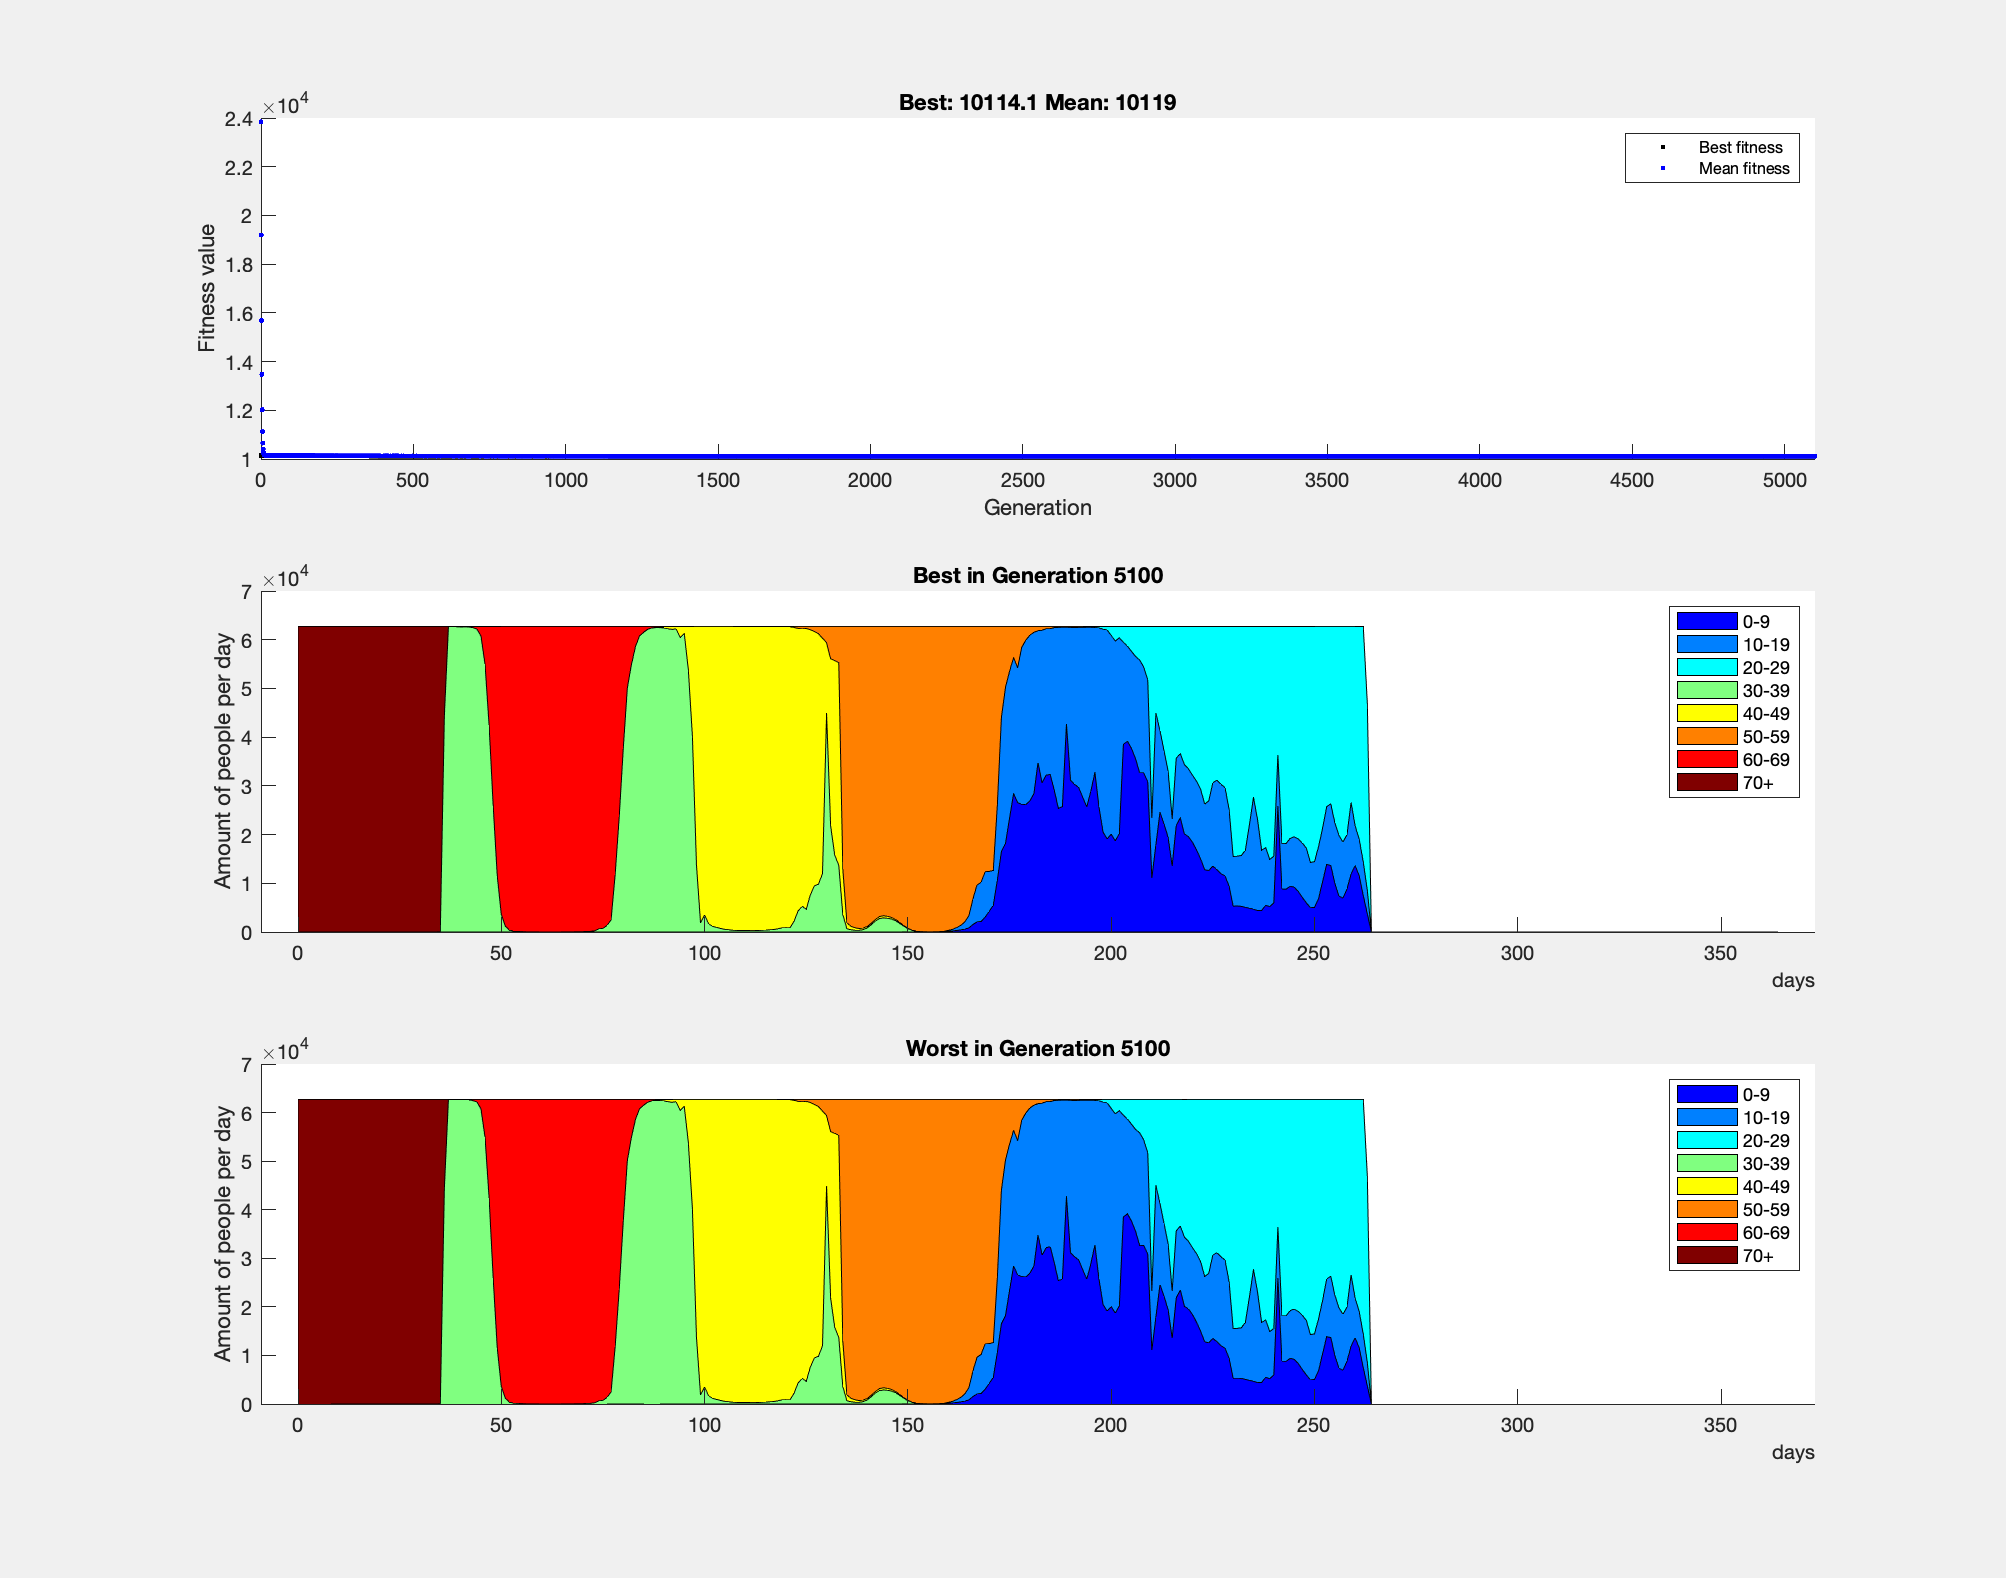

ans =   1×8 Area array:

    Area    Area    Area    Area    Area    Area    Area    Area


ga_VS.plotArea()

ga_score

ga_score = 1.0114e+04

## Differential Evolution.

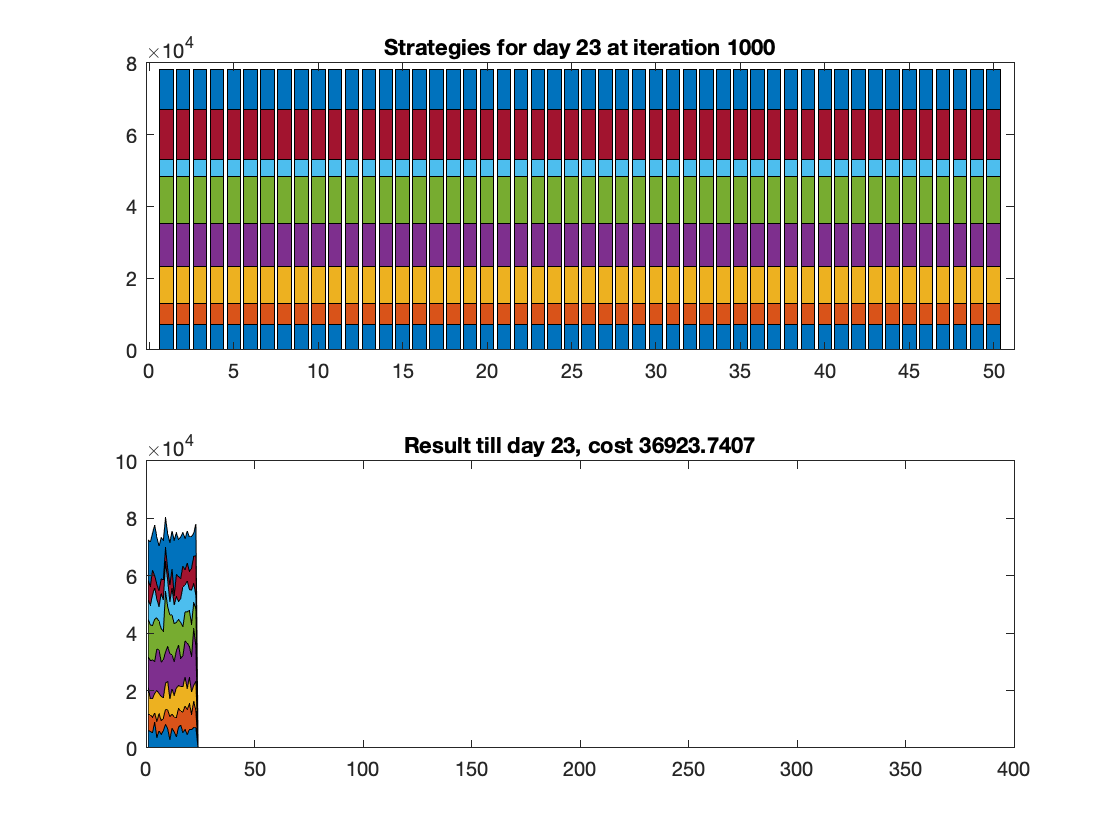

[de_VS, de_score] = P.runDifferentialEvolution( ...
    'Iterations', 1000 , ...
    'PopulationSize', 50 ...
);

de_VS.plotArea()
de_score